# Beat Tracking 

## Sound data

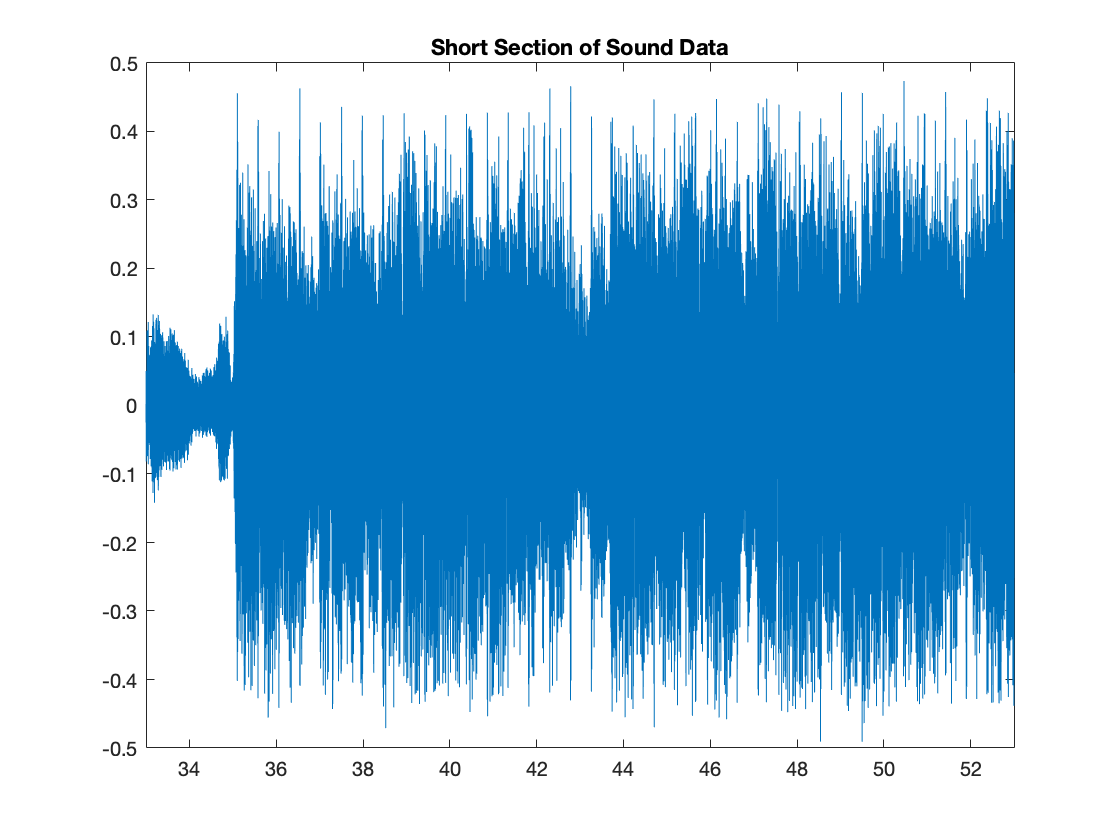

%Import sound data
%track_name = 'fortroad_lost.wav';
%track_name = 'heybrother_avicii.wav';
track_name = 'Avicii - Hey Brother.wav';
%track_name = 'fortroad_lost 3.wav';
[x fs]=audioread(track_name);

%Create a time index
t=0:1/fs:(length(x)-1)/fs;

%'Trim' size of file down to sec seconds duration
duration = 20; %Choose duration in seconds
start_time = 33; %Choose start time in seconds

finish_time = start_time + duration;
trimi = find(start_time-1/fs <= t & t <= start_time+1/fs);
trimf = find(finish_time-1/fs <= t & t <= finish_time+1/fs);
xshort=x(trimi:trimf);
tshort = t(trimi:trimf);

figure
plot(tshort,xshort)
xlim([start_time finish_time])
title("Short Section of Sound Data");


%Play sound
%soundsc(xshort,fs)

## Moving Average Power

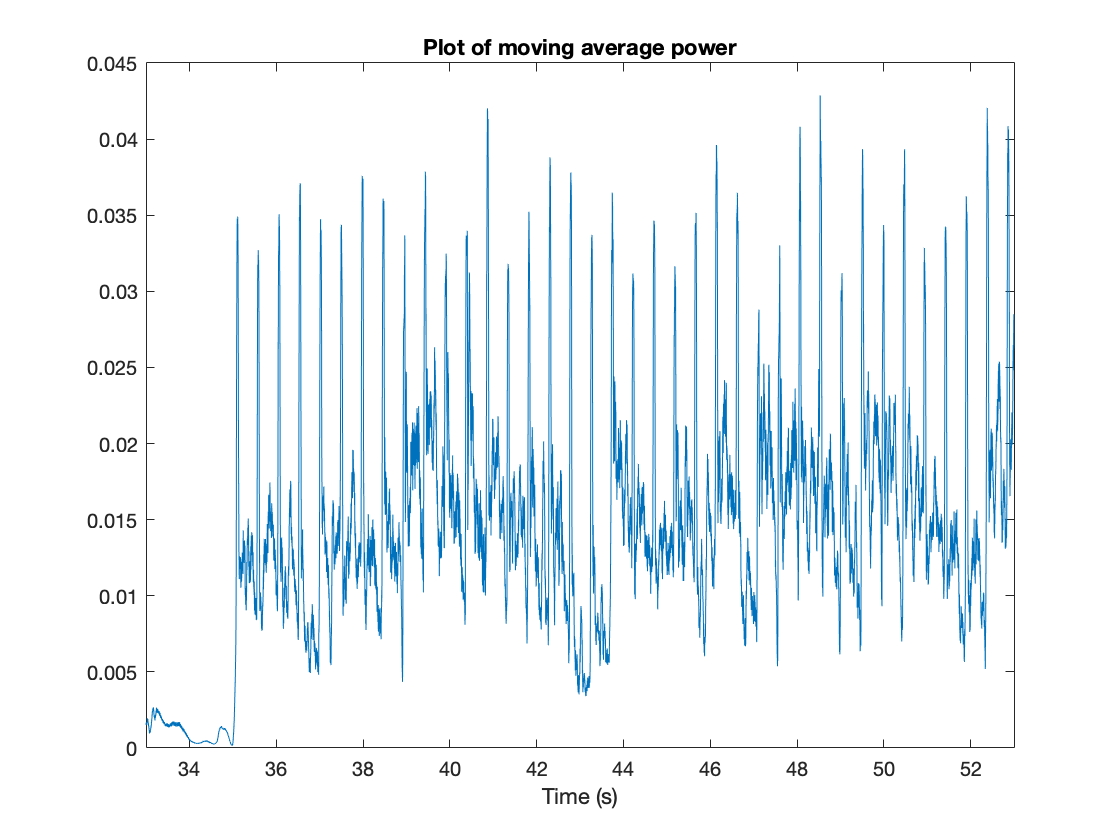

%Moving Average Power
%pshort = movmean(xshort.^2, 5);
pshort = movmean(xshort.^2, 2000);

figure
plot(tshort,pshort)
xlim([start_time finish_time])
title("Plot of moving average power")
xlabel('Time (s)')

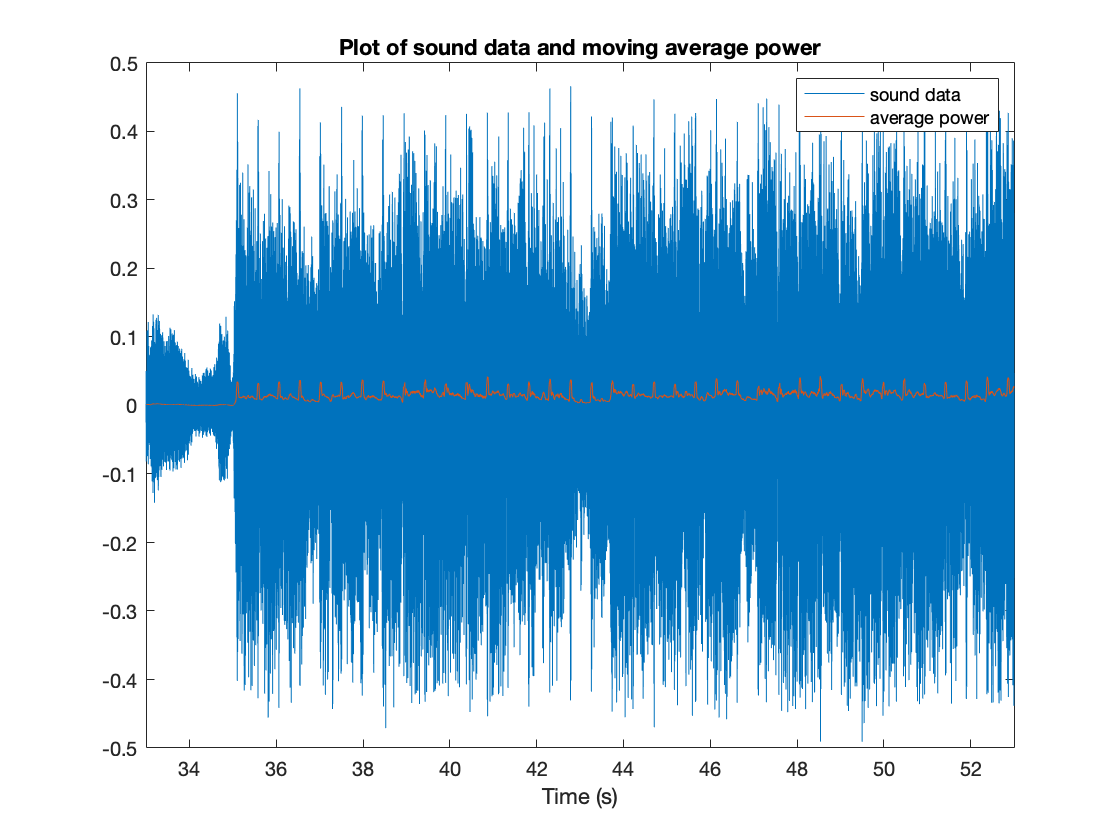


%Plot moving ave pwr and sound on same axes
figure
plot(tshort,xshort)
xlim([start_time finish_time])
hold on
plot(tshort,pshort)
hold off
title("Plot of sound data and moving average power")
xlabel('Time (s)')
legend('sound data', 'average power')

## Auto-Correlation

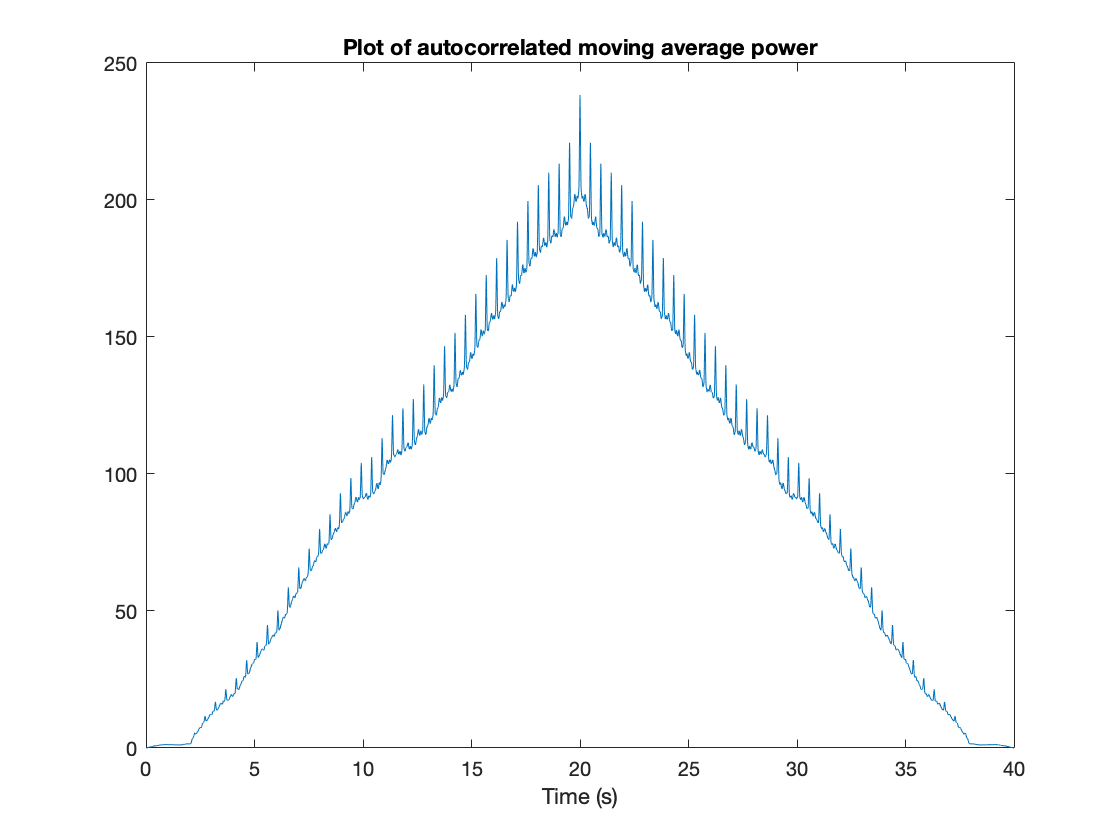

%Perform an auto-correlation on the moving ave power
acpshort = xcorr(pshort);
%Create a time axis
tACF=0:1/fs:(length(acpshort)-1)/fs;

%Plot the autocorrelation of the moving ave pwr
figure
plot(tACF,acpshort)
title("Plot of autocorrelated moving average power")
xlabel('Time (s)')

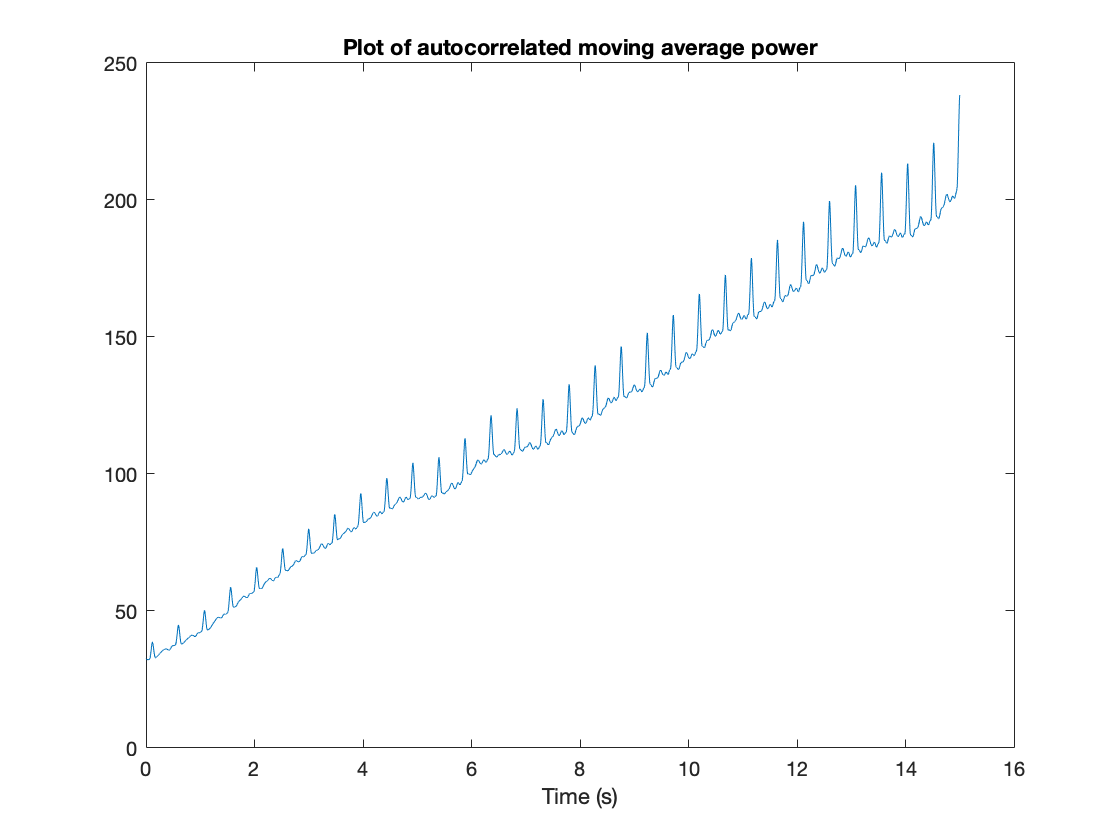


% Discard second (symmetric) half and first 5 seconds
acpshortHalf=acpshort(round(5*fs):round(length(acpshort)/2));
tACF2=0:1/fs:(length(acpshortHalf)-1)/fs;
figure
plot(tACF2,acpshortHalf)
title("Plot of autocorrelated moving average power")
xlabel('Time (s)')

## Calculate BPM

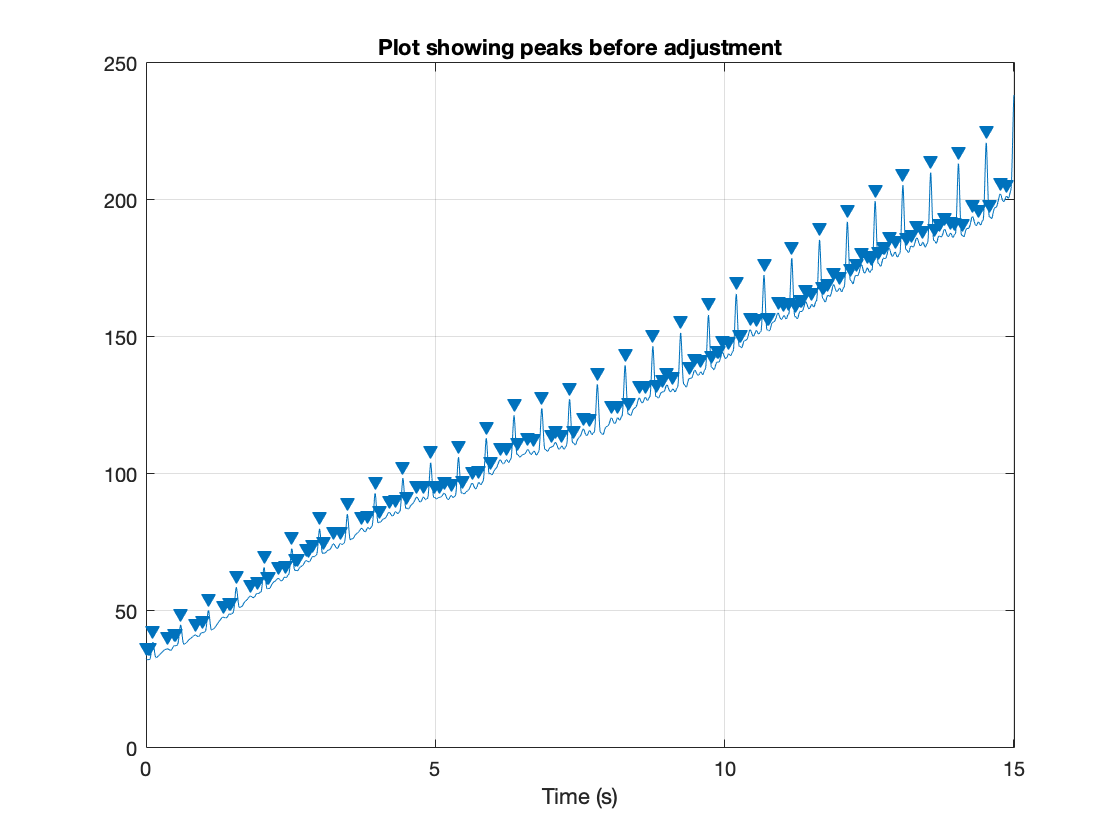

% Find peaks and corresponding times
[pks,times] = findpeaks(acpshortHalf,fs);

figure
findpeaks(acpshortHalf,fs);
title("Plot showing peaks before adjustment")
xlabel('Time (s)')


% Remove invalid peaks
for i=2:length(pks)
    % If the value of the peak is less than the previous
    % peak, remove its time
    if pks(i)<pks(i-1)
        times(i)=0; % Set time to zero and remove later
        pks(i)=pks(i-1);
    end
end
times(times==0)=[]; % Remove invalid times

timeDifference=mean(diff(times)); % Get the time difference between the peaks
BPM=(1/timeDifference)*60;
disp("BPM calculated -> " + BPM)

BPM calculated -> 128.1873


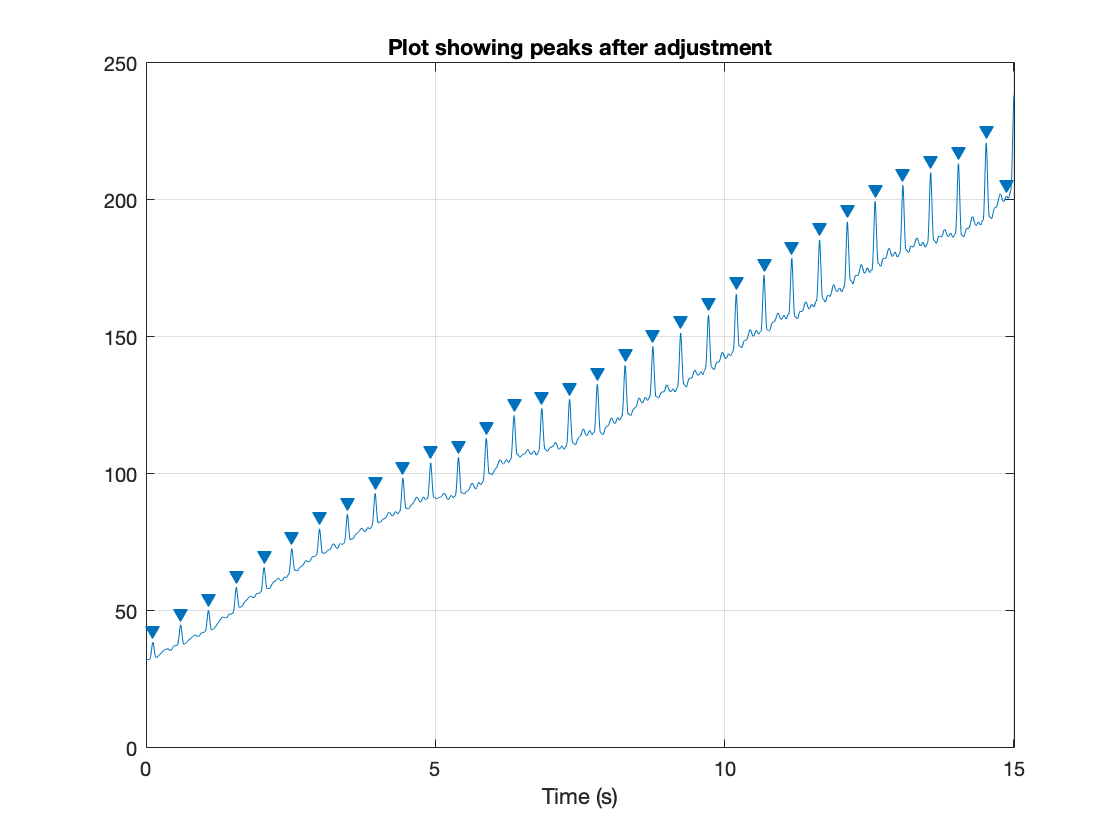


% Plot points on AC function
% Use time difference found as a constraint
minPeakDistance=timeDifference*0.6;

figure
findpeaks(acpshortHalf,fs,'MinPeakDistance',minPeakDistance);
title("Plot showing peaks after adjustment")
xlabel('Time (s)')


%Observations
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Fortroad - Lost
%189300 - 158200 -> 31100 %Difference between two adjacent peaks in the auto
%correlation of moving pwr -> 85.1 bpm (Actual ~85)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Avicii - Hey Brother
%(241700 - 199300)/2 -> 21200 -> 124.8 bpm (Actual ~125)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Belwoorf - Nostalgia first 5 seconds
%126100 - 110400 -> 15700 -> 168.5 bpm (Actual is either ~168 or 84)

## Frequency Domain

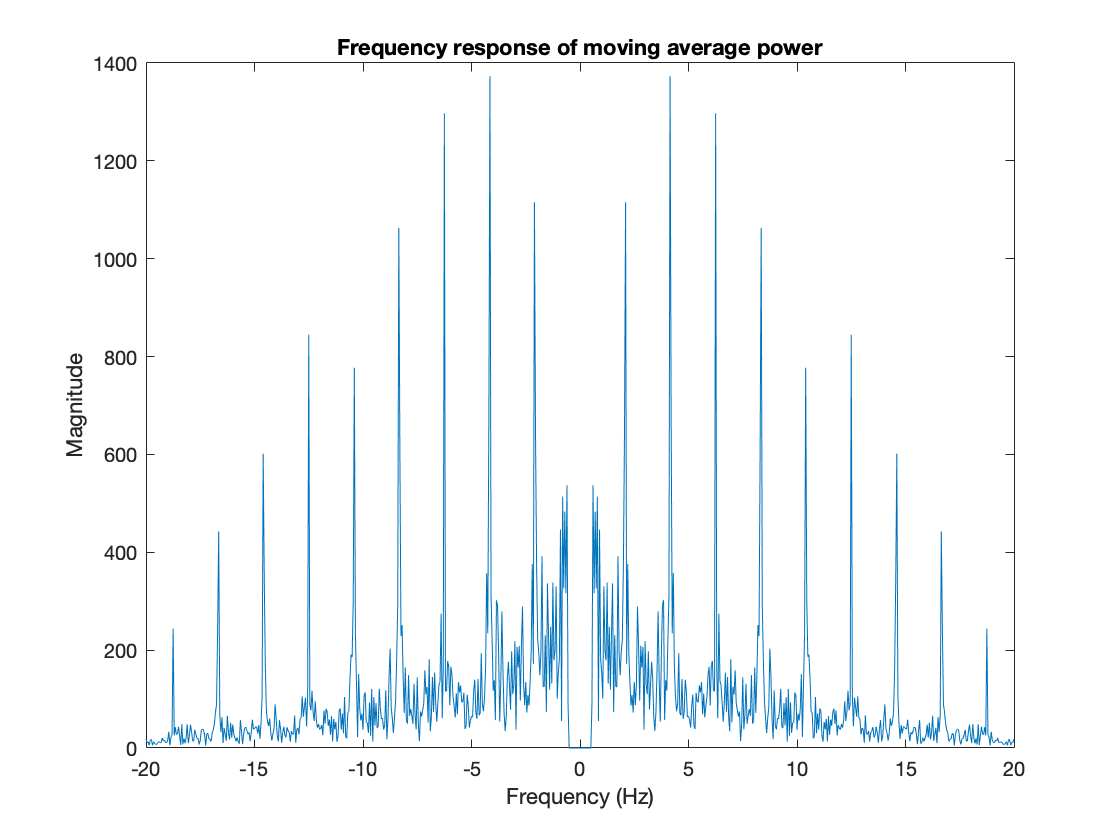

% Frequency plots
n=-(length(pshort)-1)/2:(length(pshort)-1)/2;
f=(fs/length(pshort))*n;

FTP=fftshift(fft(pshort));
% Constraints
% A song will typically have a tempo between 50 bpm (0.83 Hz)
% and 200 bpm (3.33 Hz)
%FTP(f<=0.83 & f>=-0.83)=0;
FTP(f<=0.5 & f>=-0.5)=0;
FTP(f>=3.34 & f<=-3.34)=0;
figure
%subplot(2,1,1)
plot(f,abs(FTP))
xlim([-20 20])
title("Frequency response of moving average power")
xlabel("Frequency (Hz)")
ylabel("Magnitude")

%subplot(2,1,2)
%plot(f,angle(fftshift(fft(y))))
%xlabel("Frequency (Hz)")
%ylabel("Phase")

% The tempo is typically the lower dominant frequency 
